# A tutorial on how to use the Brain Observatory Toolbox

This tutorial will show you how to access the Brain Observatory data using MATLAB. In particular, this tutorial will show you how to:

1) Instantiate a `sessionfilter` object to:

    A) Get general information on the brain observatory data

    B) Filter sessions by specified criteria such as brain areas, imaging depth and stimuli type

2) Instantiate a `session` object to:

     Retrieve and examine kinds of experiment data as listed below of an interetsed session from its Neurodata Without Borders (NWB) file:

        a) ROI masks

        b) fluorescence traces

        c) running speed

        d)  motion correction

        e) eye tracking

3) Call function `convert_fluorescence_trace_into_raster_format` to:

        Convert fluorescence trace into data that is in "raster format" for further analysis

## Organization of the Brain Observatory Data

Before we start, we first want to describe the organization of the Brain Observatory Data. 

An *experiment container* contains three *sessions* (also called *experiments* or *ophys_experiments*) where recordings were made on a singe mouse, in a single brain region and at a particular imaging depth. Each of these three sessions consists of a series of "subexperiments" where a particular stimulus set was shown. Neurodata Without Borders (NWB) files downloaded from the Allen Institute API each consist of data from a single session. As described below, all data that we extract into "raster format" consists of data from a single "subexperiment" where a particular stimulus set was shown. 

Note: within an experiment container the same stimuli might be repeated in different sessions (i.e., different sessions can have the same "subexperiment type").  For example, Natural Movie 1 is shown in all three sessions in an experiment container. For more information see: [http://alleninstitute.github.io/AllenSDK/brain_observatory.html](http://alleninstitute.github.io/AllenSDK/brain_observatory.html)

## 1) Instantiate a `sessionfilter` object

`sessionfilter` is a class that resembels BrainObservatoryCache in allensdk (see Python code at:[https://github.com/AllenInstitute/AllenSDK/blob/master/allensdk/core/brain_observatory_cache.py](https://github.com/AllenInstitute/AllenSDK/blob/master/allensdk/core/brain_observatory_cache.py)).

The MATLAB `sessionfilter` enables you to get information and access data using three types of methods:

A) Get general information on the brain observatory data using methods that start with "get_" 

B) Filter sessions by different criteria using methods that start with "filter_"

To beign, build a `brain_observatory_cache` object

bosf1 = bot.sessionfilter()

bosf1 =   sessionfilter with properties:

       valid_session_table: [543×15 table]
    filtered_session_table: [543×15 table]
                  stimulus: {9×1 cell}
        targeted_structure: {6×1 cell}
             imaging_depth: [10×1 double]
              container_id: [181×1 double]
                session_id: [543×1 double]
              session_type: [543×1 categorical]
                  cre_line: {6×1 cell}
        eye_tracking_avail: [2×1 logical]


## 1A) Get general information on the brain observatory data

There are several methods start with "get_" which summairze in the brain observatory data based on particular criteria. 

To get the total number of experiment containers we can use:

bosf1.get_total_num_of_containers()

ans = 181

Note: Total number of sessions is the number of containers times 3 since there are three sessions per container.

To get all the cortical depths (um) that were ever recorded in any experiment container we can use:

bosf1.get_all_imaging_depths()

ans =    175
   265
   275
   300
   320
   325
   335
   350
   365
   375


Note: Recordings didn't take place equally among these depths, only the most common depths are shown on homepage of Brain Observatory: [http://observatory.brain-map.org/visualcoding](http://observatory.brain-map.org/visualcoding)

To get all the get all type of cre driver lines from all mice we can use:

bosf1.get_all_cre_lines()

ans = 6×1 cell array
    'Cux2-CreERT2'
    'Emx1-IRES-Cre'
    'Nr5a1-Cre'
    'Rbp4-Cre_KL100'
    'Rorb-IRES2-Cre'
    'Scnn1a-Tg3-Cre'


Note: All mice had the same reporter line: Ai93 and tTA driver line: Camk2a-tTA

For more information about transgenic lines: [http://observatory.brain-map.org/visualcoding/transgenic](http://all mice had the same reporter line: Ai93 and driver line: Camk2a-tTA; there were several cre lines as shown here. % for more information about transgenic lines: http://observatory.brain-map.org/visualcoding/transgenic)

To get all the all brain regions that were recorded in any experiment container we can use:

bosf1.get_all_targeted_structures()

ans = 6×1 cell array
    'VISal'
    'VISam'
    'VISl'
    'VISp'
    'VISpm'
    'VISrl'


For more information on these locations, see homepage of Brain Observatoy: [http://observatory.brain-map.org/visualcoding](http://observatory.brain-map.org/visualcoding)

To get all the all types of sessions that appear in any experiment container we can use:

bosf1.get_all_session_types()

ans = 4×1 cell array
    'three_session_A'
    'three_session_B'
    'three_session_C'
    'three_session_C2'


Note: There are always three sessions in each container: session A, session B,  and session C or session C2

To get all the  all type of stimuli that were used in any of the four types of sessions we can use:

bosf1.get_all_stimuli()

ans = 9×1 cell array
    'drifting_gratings'
    'locally_sparse_noise_4deg'
    'locally_sparse_noise_8deg'
    'natural_movie_one'
    'natural_movie_three'
    'natural_movie_two'
    'natural_scenes'
    'spontaneous'
    'static_gratings'


Note: For mapping between session type and stimulus type see [http://alleninstitute.github.io/AllenSDK/brain_observatory.html](http://alleninstitute.github.io/AllenSDK/brain_observatory.html)

To get the number of experiment containers recorded in each brain region we can use:


bosf1.get_summary_of_containers_along_targeted_structures()

     VISal      35 
     VISam      25 
     VISl       38 
     VISp       66 
     VISpm      36 
     VISrl      16 


To get the number of experiment containers recorded at each cortical depth we can use:

bosf1.get_summary_of_containers_along_imaging_depths()

     175      53 
     250       1 
     265       1 
     275      75 
     300       4 
     320       1 
     325       3 
     335       3 
     350      33 
     365       1 
     375      40 
     435       1 


To get the number of experiment containers recorded at each cortical depth in each brain region we can use:

bosf1.get_summary_of_containers_along_depths_and_structures()

ans = 11×7 table
             VISal    VISam    VISl    VISp    VISpm    VISrl    total
             _____    _____    ____    ____    _____    _____    _____

    175       8        5       10      11      11        5        50  
    265       1        0        0       0       0        0         1  
    275      11        9       14      17       9        5        65  
    300       1        0        1       1       1        0         4  
    320       0        1        0       0       0        0         1  
    325       0        1        1       0       1        0         3  
    335       0        0        0       2       1        

## 1B) Filter sessions by specified criteria such as brain areas, imaging depth and stimuli type

`sessionfilter.filtered_session_table` is an m-by-n table listing the n fields of meta data of m succesful sessions. As different filter methods get called on `sessiionfilter`, rows/sessions in `filtered_session_table` are liminated to meet specified criteria, and other properies (e.g., stimuli, targeted_structure, etc) of `sessionfilter,` that are essentially important fields of  meta data in `filtered_session_table`, are also updated.  

Here we show an example of searching for sessions that Rorb-IRES2-Cre mice had their primary visual cortex recorded at 275 μm deep, during where drifting gratings were shown and eye tracking went through.

To ensure an "inviolate" `sessionfilter`:

bosf1.clear_filters

Eliminate sessions to the ones where drifting gratings were shown:

bosf1.filter_sessions_by_stimuli('drifting_gratings')

ans =   sessionfilter with properties:

       valid_session_table: [543×15 table]
    filtered_session_table: [181×15 table]
                  stimulus: {4×1 cell}
        targeted_structure: {6×1 cell}
             imaging_depth: [10×1 double]
              container_id: [181×1 double]
                session_id: [181×1 double]
              session_type: [181×1 categorical]
                  cre_line: {6×1 cell}
        eye_tracking_avail: [2×1 logical]


Note that several properties of `bosf `have changed.

Eliminate sessions to the ones that have posterior Primary Visual Cortex recordings:

bosf1.filter_sessions_by_targeted_structure('VISp')

ans =   sessionfilter with properties:

       valid_session_table: [543×15 table]
    filtered_session_table: [46×15 table]
                  stimulus: {4×1 cell}
        targeted_structure: {'VISp'}
             imaging_depth: [6×1 double]
              container_id: [46×1 double]
                session_id: [46×1 double]
              session_type: [46×1 categorical]
                  cre_line: {6×1 cell}
        eye_tracking_avail: [2×1 logical]


Eliminate sessions to the ones that were recoreded at 275 um deep

bosf1.filter_sessions_by_imaging_depth(275)

ans =   sessionfilter with properties:

       valid_session_table: [543×15 table]
    filtered_session_table: [17×15 table]
                  stimulus: {4×1 cell}
        targeted_structure: {'VISp'}
             imaging_depth: 275
              container_id: [17×1 double]
                session_id: [17×1 double]
              session_type: [17×1 categorical]
                  cre_line: {4×1 cell}
        eye_tracking_avail: [2×1 logical]


Eliminate sessions to the ones that were operated on mice of Rorb-IRES2-Cre

bosf1.filter_session_by_cre_line('Rorb-IRES2-Cre')

ans =   sessionfilter with properties:

       valid_session_table: [543×15 table]
    filtered_session_table: [5×15 table]
                  stimulus: {4×1 cell}
        targeted_structure: {'VISp'}
             imaging_depth: 275
              container_id: [5×1 double]
                session_id: [5×1 double]
              session_type: [5×1 categorical]
                  cre_line: {'Rorb-IRES2-Cre'}
        eye_tracking_avail: [2×1 logical]


Eliminate sessions to the ones that eye tracking completely went through

bosf1.filter_session_by_eye_tracking(1)

ans =   sessionfilter with properties:

       valid_session_table: [543×15 table]
    filtered_session_table: [2×15 table]
                  stimulus: {4×1 cell}
        targeted_structure: {'VISp'}
             imaging_depth: 275
              container_id: [2×1 double]
                session_id: [2×1 double]
              session_type: [2×1 categorical]
                  cre_line: {'Rorb-IRES2-Cre'}
        eye_tracking_avail: 1


As we can see now, there are 2 sessions belonging to 2 diffrerent containers that meet all of the criteria given.

Every experiment container in the Brain Obervatory has an unique experiment container ID that was created by the Allen Institute. These container IDs are stored in the `experiment_container_id`  field in `filtered_session_table`.  For example, to see the experiment container IDs that met our filtering criteria we can run: 

bosf1.filtered_session_table.experiment_container_id

ans =    512124562
   511510989


If we want to find out the three sessions in the first experiment contianer, we can call:

bosf2 = bot.sessionfilter

bosf2 =   sessionfilter with properties:

       valid_session_table: [543×15 table]
    filtered_session_table: [543×15 table]
                  stimulus: {9×1 cell}
        targeted_structure: {6×1 cell}
             imaging_depth: [10×1 double]
              container_id: [181×1 double]
                session_id: [543×1 double]
              session_type: [543×1 categorical]
                  cre_line: {6×1 cell}
        eye_tracking_avail: [2×1 logical]


bosf2.filter_sessions_by_container_id(bosf1.filtered_session_table.experiment_container_id(1))

ans =   sessionfilter with properties:

       valid_session_table: [543×15 table]
    filtered_session_table: [3×15 table]
                  stimulus: {8×1 cell}
        targeted_structure: {'VISp'}
             imaging_depth: 275
              container_id: 512124562
                session_id: [3×1 double]
              session_type: [3×1 categorical]
                  cre_line: {'Rorb-IRES2-Cre'}
        eye_tracking_avail: 1



bosf2.session_id

ans =    512124564
   512176430
   512270518


Now let's dig into the real data.

## 2) Instantiate a `session` object to:

      Retrieve and examine kinds of experiment data as listed below of an interetsed session from its Neurodata Without Borders (NWB) file:

To illustrate this, let's instantiate a `session` object for the first session in `bosf1`. 

bos1 = bot.session(bosf1.session_id(1))

bos1 =   session with properties:

               sSessionInfo: [1×1 struct]
    strLocalNWBFileLocation: 'C:\Users\14868\Documents\GitHub\Brain-Observatory-Toolbox\+bot\Cache\external\neuralcoding\prod6\specimen_504614281\ophys_experiment_512270518\512270518.nwb'


Alternatively, we can instantiate an array of `session` objects for both sessions in `bosf1` and replace `bos1` with `bos0(1)` in the codes below.

bos0 = bosf1.get_filtered_sessions

bos0 =   1×2 session array with properties:

    sSessionInfo
    strLocalNWBFileLocation


All the meta data stored in `bosf2.filtered_session_table` for this session are carried over to `bos1.sSessionInfo`

bos1.sSessionInfo

ans = struct with fields:
        date_of_acquisition: '2016-04-07T15:29:01Z'
    experiment_container_id: 512124562
          fail_eye_tracking: 0
                         id: 512270518
              imaging_depth: 275
                       name: '20160407_234831_3stimA'
                specimen_id: 504614281
              stimulus_name: 'three_session_A'
          storage_directory: '/external/neuralcoding/prod6/specimen_504614281/ophys_experiment_512270518/'
      targeted_structure_id: 385
       experiment_container: [1×1 struct]
           well_known_files: [1×1 struct]
         targeted_structure: [1×1 struct]
                   specimen: [1×1 struct]
                   cre_line: 'Rorb-IRES2-Cre'


## 2a) ROI Masks

If you want to take a look at specific cells or all cells visually, you can extract and plot thier pixel masks. You can also pull out the maximum intensity projection of the movie for context.

% get all the cell ids
cell_ids = bos1.get_cell_specimen_ids()

cell_ids = 90×1 int64 column vector
   517447852
   517447402
   517447618
   517447321
   517447330
   517447325
   517447730
   517447755
   517447745
   517447847


When you call this or any other method of session class, BOT automatiacally searchs for the corresponding NWB file and downloads it if it is not there yet.

Dowanloading an NWB file from their server can take about 20 min.

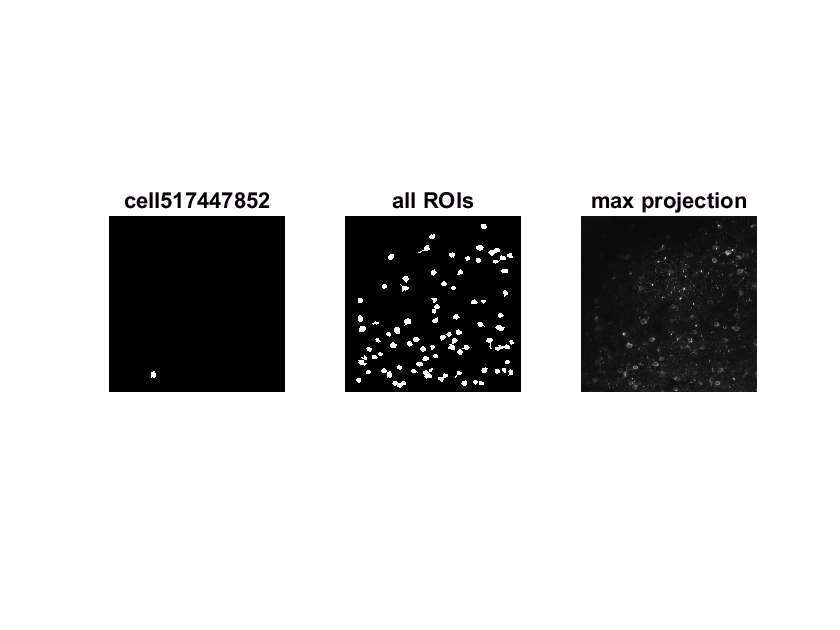


% plot the ROI mask for the first cell in the list
subplot(1,3,1)
imshow(bos1.get_roi_mask_array(cell_ids(1)))
title(['cell' num2str(cell_ids(1))])

% plot the ROI masks for all celss
all_mask = logical(zeros(512,512));
for iCell = 1: length(cell_ids)
    all_mask = or(all_mask, bos1.get_roi_mask_array(cell_ids(iCell)));
end
subplot(1,3,2)
imshow(all_mask)
title('all ROIs')

% plot the maximum intensity projection
subplot(1,3,3)
imshow(double(bos1.get_max_projection)/max(max(double(bos1.get_max_projection))))
% colormap(gray)
title('max projection')

## 2b) Fluorescence Traces

You can get the fluorescence traces of a specific cell by its index. Let's take cell 589163560 as an example.

[time, raw] = bos1.get_fluorescence_traces;
[time, demixed] = bos1.get_demixed_traces;
[time, neuropil] = bos1.get_neuropil_traces;

neuropil_r = bos1.get_neuropil_r;

[time, corrected] = bos1.get_corrected_fluorescence_traces;

% % compute it yourself
% corrected = demixed - neuropil * (neuropil_r .* eye(size(neuropil_r,1)));


[time, dff] = bos1.get_dff_traces;

iCell = bos1.get_cell_specimen_indices(cell_ids(1))

iCell = 1

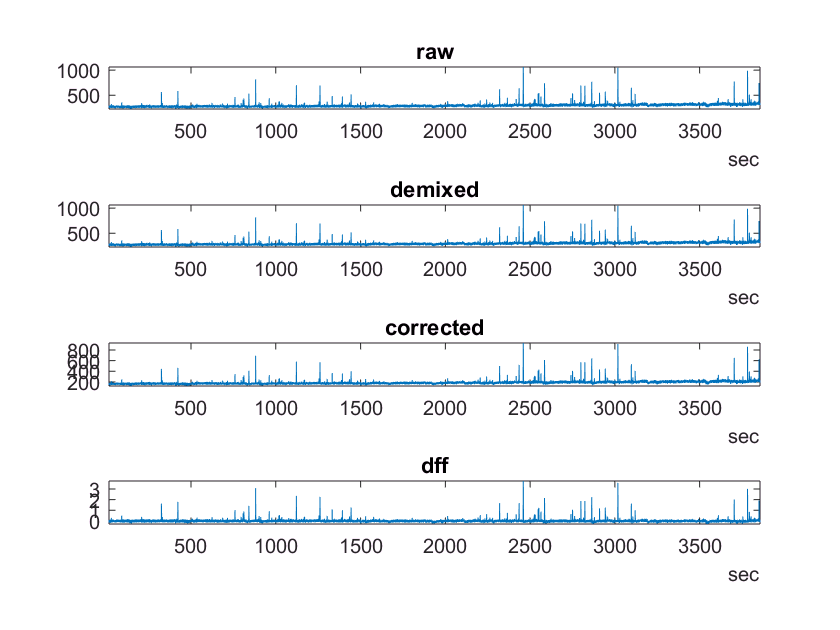


subplot(4,1,1)
plot(time, raw (:,iCell))
axis tight
title ('raw')

subplot(4,1,2)
plot(time, demixed (:,iCell))
axis tight
title ('demixed')

subplot(4,1,3)
plot(time, corrected(:,iCell))
axis tight
title ('corrected')

subplot(4,1,4)
plot(time, dff(:,iCell))
axis tight
title ('dff')

You can also examine the fluorescence traces of all cells recorded in a session one cell at a time in sequence. The traces will be plotted in an external figure, hit any key to proceed to the next cell. 

figure('Position', get(0, 'Screensize'))
set(gcf, 'Visible','on')

for iCell = 1:length(cell_ids)
clf

ft_to_be_plotted = {'raw', 'demixed', 'corrected', 'dff'};

for ift = 1: length(ft_to_be_plotted)
subplot(length(ft_to_be_plotted),1,ift)
cur_ft = eval(ft_to_be_plotted{ift});
plot(time, cur_ft(:,iCell))
% axis tight
ylim([0,max(max(cur_ft))])
title(ft_to_be_plotted{ift})
end

fprintf('Program paused. Press any key to continue to the next cell.\n');
pause;
end

Program paused. Press any key to continue to the next cell.


Program paused. Press any key to continue to the next cell.


Program paused. Press any key to continue to the next cell.


Program paused. Press any key to continue to the next cell.


Program paused. Press any key to continue to the next cell.


close all

## 2c) Running Speed

All experiments contain running speed. Extreme outliers from the tracking have been removed and replaced with NaN, which will appear as gaps in the plotted data.

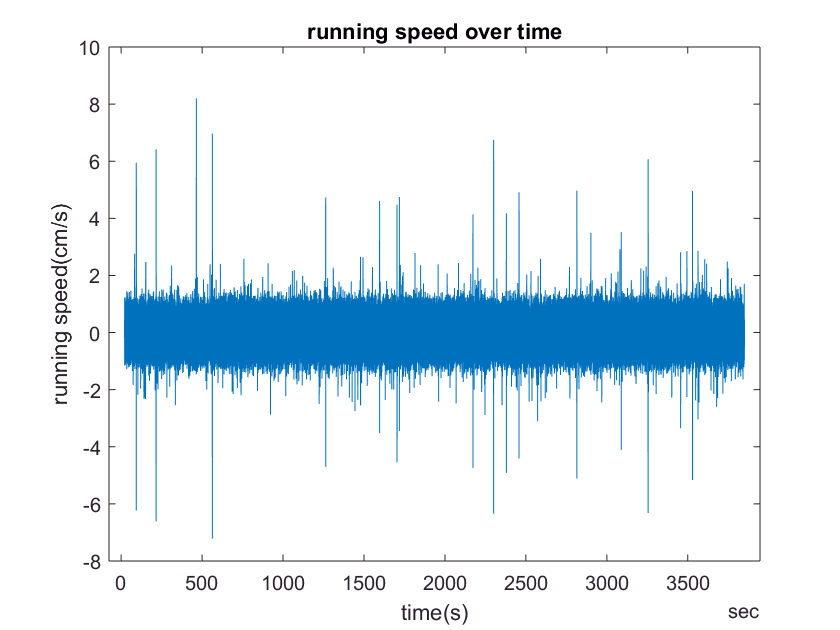

[time, runningSpeed] = bos1.get_running_speed;
plot(time, runningSpeed)
title('running speed over time')
xlabel('time(s)')
ylabel('running speed(cm/s)')

As you can see here, the mouse in this session didn't run much. Here is another session 580124131, whose running data is more exciting: 

bos2 = bot.session(580124131)

bos2 =   session with properties:

               sSessionInfo: [1×1 struct]
    strLocalNWBFileLocation: 'C:\Users\14868\Documents\GitHub\Brain-Observatory-Toolbox\+bot\Cache\external\neuralcoding\prod22\specimen_571153214\ophys_experiment_580124131\580124131.nwb'


bos2.sSessionInfo

ans = struct with fields:
        date_of_acquisition: '2017-04-07T17:11:58Z'
    experiment_container_id: 580051757
          fail_eye_tracking: 0
                         id: 580124131
              imaging_depth: 375
                       name: '20170407_300663_3StimB'
                specimen_id: 571153214
              stimulus_name: 'three_session_B'
          storage_directory: '/external/neuralcoding/prod22/specimen_571153214/ophys_experiment_580124131/'
      targeted_structure_id: 417
       experiment_container: [1×1 struct]
           well_known_files: [1×1 struct]
         targeted_structure: [1×1 struct]
                   specimen: [1×1 struct]
                   cre_line: 'Rbp4-Cre_KL100'


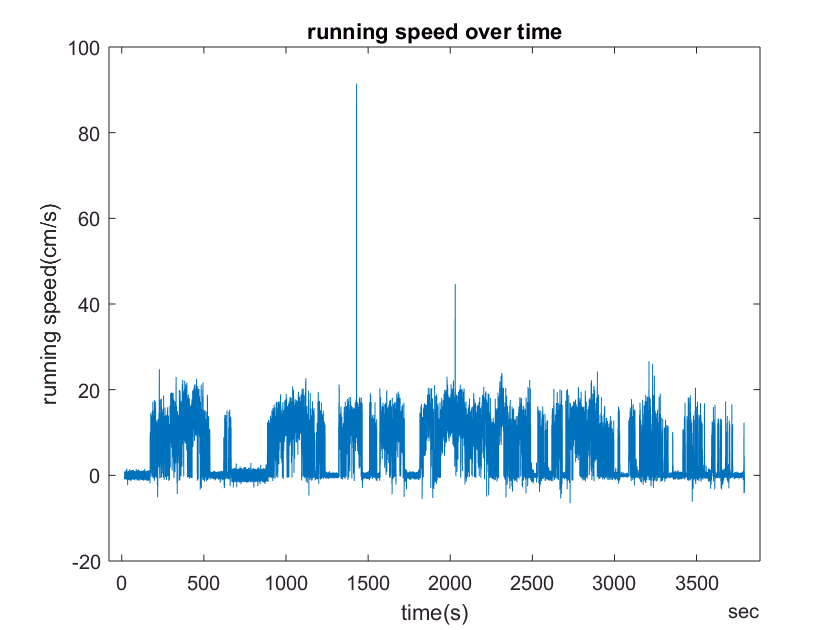

[time, runningSpeed] = bos2.get_running_speed;
plot(time, runningSpeed)
title('running speed over time')
xlabel('time(s)')
ylabel('running speed(cm/s)')

## 2d) Motion Correction

X and Y translation values in pixels required to correct for motion artifacts during the experiment are available as well.

As you can expect, since the mouse in bos2 ran more than the mouse in bos1, there was more motion correction in bos2 than in bos1.

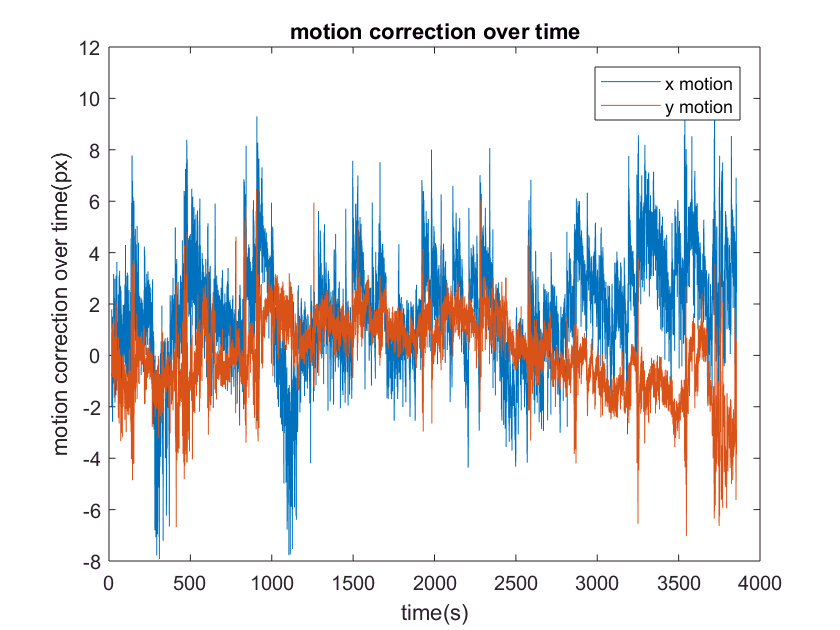

close all
mc = bos1.get_motion_correction;
plot(table2array(mc(:,'timestamp')), table2array(mc(:,'x_motion')),table2array(mc(:,'timestamp')), table2array(mc(:,'y_motion')))
title('motion correction over time')
xlabel('time(s)')
ylabel('motion correction over time(px)')
legend('x motion','y motion')
xlabel('time(s)')

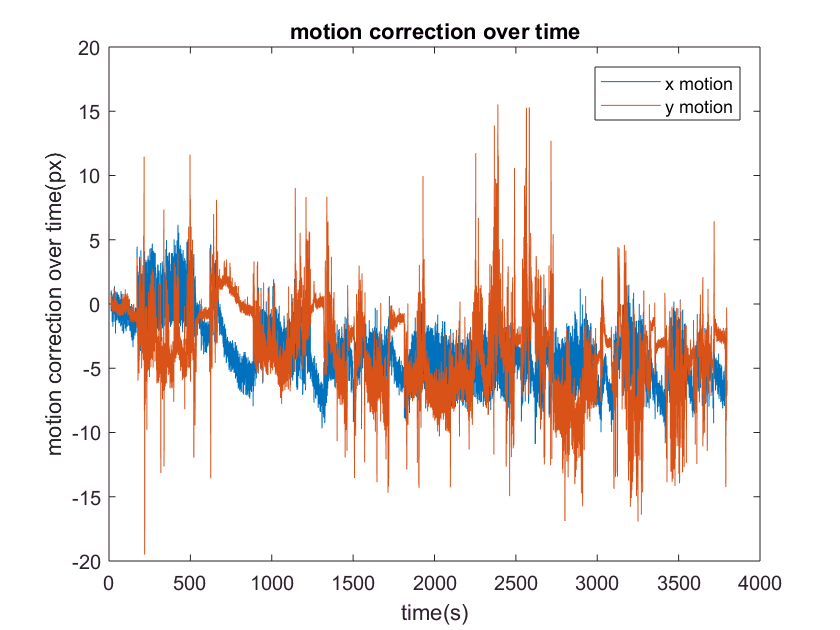

mc = bos2.get_motion_correction;
plot(table2array(mc(:,'timestamp')), table2array(mc(:,'x_motion')),table2array(mc(:,'timestamp')), table2array(mc(:,'y_motion')))
title('motion correction over time')
xlabel('time(s)')
ylabel('motion correction over time(px)')
legend('x motion','y motion')
xlabel('time(s)')

## Eye Tracking

Many experiments contain pupil position and pupil size from eye tracking. Extreme outliers from the tracking have been removed and replaced with NaN, which will appear as gaps in the plotted data. If an experiment does not have eye tracking data, a NoEyeTrackingException will be raised.

As shown in `bos1.sSessionInfo`,  the session in `bos1` doesn't have eye tracking data, so let's filer out all sessions with eye tracking data and takes the first session in the list to demonstrate this functionality.

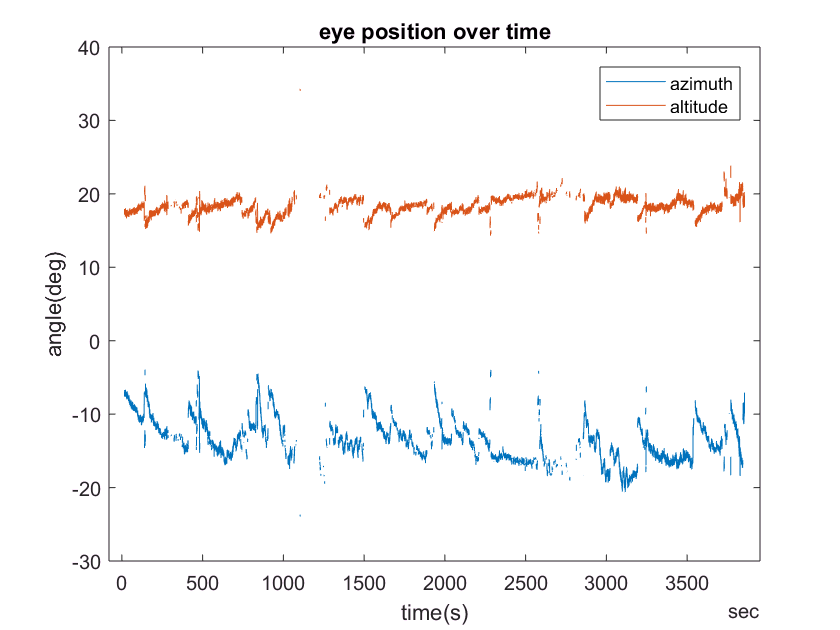


[time, pupilLocation] = bos1.get_pupil_location;
azimuth = pupilLocation(:,1);
altitude = pupilLocation(:,2);
plot(time, azimuth, time, altitude)
title('eye position over time')
legend ('azimuth', 'altitude')
xlabel('time(s)')
ylabel('angle(deg)')

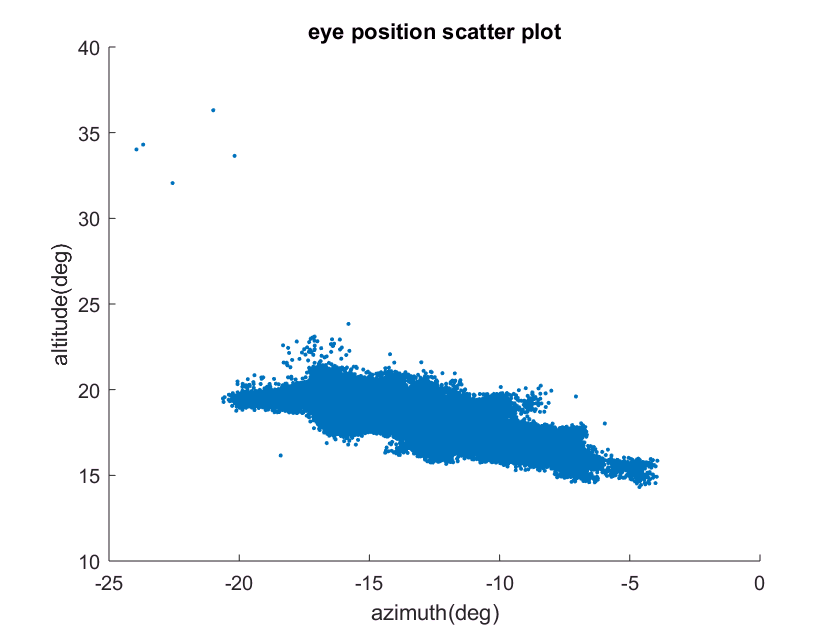




scatter(azimuth, altitude, '.')
title('eye position scatter plot')
xlabel('azimuth(deg)')
ylabel('altitude(deg)')

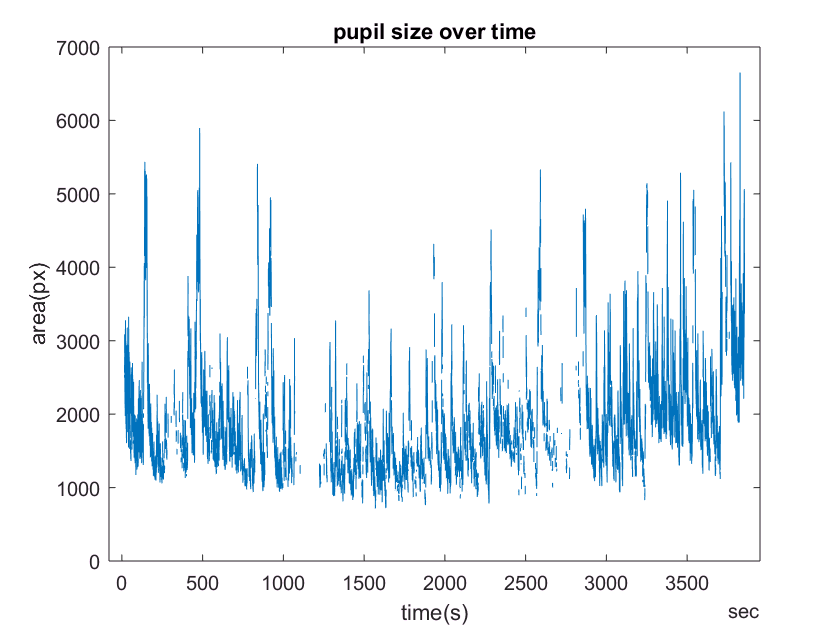

[time, pupilArea] = bos1.get_pupil_size;
plot(time, pupilArea)
title('pupil size over time')
xlabel('time(s)')
ylabel('area(px)')

## 3) Call function `convert_fluorescence_trace_into_raster_format` to:

        Convert fluorescence trace into data that is in "raster format" for further analysis

 bot.util.convert_fluorescence_trace_into_raster_format('DfOverF', bos1.sSessionInfo.id,'drifting_gratings','raster')

All raster files already exist in directory [raster\drifting_gratings\drifting_gratings_512270518].
